# interpolate and grid PRIZE mooring data

***Author: Lewis Drysdale, 2021***

### Interpolate, despike, and plot data from moorings deployed and recovered during ArcticPRIZE project

Data were sampled at:

-        2 hour - SBE16

-        6 min - Star-Odi

-        12 mins - SBE 37

clear; close all;

### set directories and gridding parameters

data_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\data\moor_processed'

data_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\data\moor_processed'

plot_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\figures';

### SET PARAMS FOR GRIDDING AND FILTERING

t_interp    = 1/2;         % every 6 hours
z_interp    = 10;          % every 10 metres


Despike swith 1 is ON, 0 is OFF

despike     =  1; 

### Set mooring ID for processing

mid={'WEST_17','EAST_17','EAST_18','WEST_18'};
for jah=1:numel(mid)
    mooring_id=mid{jah};
    count=0;

### BEGIN DATA PROCESSING

switch mooring_id

    case 'WEST_17'

        start_date=datenum('23-Sep-2017 12:30:00');
        end_date=datenum('13-Jun-2018 23:00:00'); 

        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_west_17_gridded]=prize_grid_linear_interp(prize_west_17,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,despike)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_west_17_gridded','prize_west_17');
        
    case 'EAST_17'

        start_date=datenum('21-Sep-2017 18:30:00'); % deployed at 15:19.
        end_date=datenum('17-Jun-2018 05:00:00'); 

        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_east_17_gridded]=prize_grid_linear_interp(prize_east_17,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,despike)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_east_17_gridded','prize_east_17');
        
    case 'EAST_18'
        
        start_date=datenum('20-Jun-2018 12:00:00');
        end_date=datenum('18-Nov-2019 14:05:00'); 
        
        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_east_18_gridded]=prize_grid_linear_interp(prize_east_18,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,despike)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_east_18_gridded','prize_east_18');

    case 'WEST_18'

        start_date=datenum('22-Jun-2018 12:30:00');
        end_date=datenum('25-Nov-2019 05:00:00'); 

        % make dir in plot folder
        if ~exist([plot_dir filesep mooring_id],'dir')==1
            mkdir([plot_dir filesep mooring_id])
        end

        % load data structure
        load([data_dir filesep mooring_id '.mat']);

        [prize_west_18_gridded]=prize_grid_linear_interp(prize_west_18,plot_dir,mooring_id,t_interp,z_interp,start_date,end_date,despike)
        % SAVE data structure
        save([data_dir filesep mooring_id '.mat'],'prize_west_18_gridded','prize_west_18');
end

## Plot the data

if strcmpi(mooring_id,'WEST_17')
    data=prize_west_17_gridded;
elseif strcmpi(mooring_id,'EAST_17')
    data=prize_east_17_gridded;
elseif strcmpi(mooring_id,'WEST_18')
    data=prize_west_18_gridded;
elseif strcmpi(mooring_id,'EAST_18')
    data=prize_east_18_gridded;
else
    disp('No data to plot!')
end

### plot the salinity data

figure(1);
ax(1)=subplot(3,1,1);
plot(data.time_grid,data.sal);
ylabel('Salinity')
xlabel('Time')
datetick('x',12,'keepticks')
title('6-hour grid')

ax(2)=subplot(3,1,2);
plot(data.time_grid,data.sal_filtered);
ylabel('Salinity')
xlabel('Time')
datetick('x',12,'keepticks')
title('6-hour grid and Low pass filtered')

ax(3)=subplot(3,1,3);
[c,h]=contourf(data.time_grid,data.pres_grid,data.sal_filtered_interpolated,30,...
    'Linecolor','none');
axis ij
cmocean('haline')
C=colorbar;
ylabel(C,'Salinity')
ylabel('Pressure')
xlabel('Time')
datetick('x',12,'keepticks')
title('6-hour and 10 decibar grid, low pass filtered')

savename=[plot_dir filesep mooring_id '_salinity_grid'];
print(gcf, '-dpng',savename);

## plot the temperature data

loop: 1;  spikes: 8


loop: 1;  spikes: 89


loop: 1;  spikes: 74


loop: 1;  spikes: 67


prize_west_17_gridded = struct with fields:
                 temp_filtered: [13×519 double]
                  sal_filtered: [13×519 double]
                 pres_filtered: [13×519 double]
    temp_filtered_interpolated: [20×519 double]
     sal_filtered_interpolated: [20×519 double]
                     pres_grid: [20×1 double]
                          temp: [13×519 double]
                           sal: [13×519 double]
                          pres: [13×519 double]
                     time_grid: [1×519 double]


loop: 1;  spikes: 167


loop: 1;  spikes: 60


loop: 1;  spikes: 53


loop: 1;  spikes: 61


prize_east_17_gridded = struct with fields:
                 temp_filtered: [13×529 double]
                  sal_filtered: [13×529 double]
                 pres_filtered: [13×529 double]
    temp_filtered_interpolated: [15×529 double]
     sal_filtered_interpolated: [15×529 double]
                     pres_grid: [15×1 double]
                          temp: [13×529 double]
                           sal: [13×529 double]
                          pres: [13×529 double]
                     time_grid: [1×529 double]


loop: 1;  spikes: 28


loop: 1;  spikes: 194


loop: 1;  spikes: 125


loop: 1;  spikes: 81


loop: 1;  spikes: 156


prize_east_18_gridded = struct with fields:
                 temp_filtered: [15×1025 double]
                  sal_filtered: [15×1025 double]
                 pres_filtered: [15×1025 double]
    temp_filtered_interpolated: [15×1025 double]
     sal_filtered_interpolated: [15×1025 double]
                     pres_grid: [15×1 double]
                          temp: [15×1025 double]
                           sal: [15×1025 double]
                          pres: [15×1025 double]
                     time_grid: [1×1025 double]


loop: 1;  spikes: 10


loop: 1;  spikes: 178


loop: 1;  spikes: 154


loop: 1;  spikes: 166


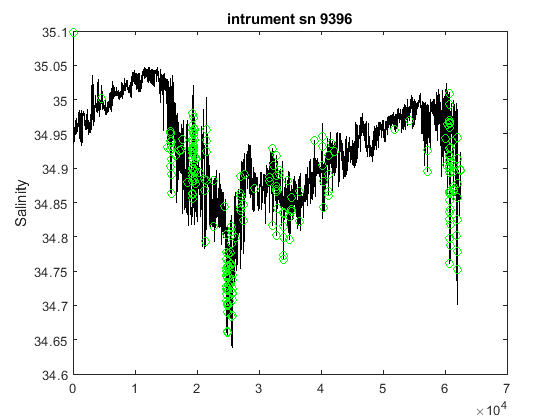

loop: 1;  spikes: 225


prize_west_18_gridded = struct with fields:
                 temp_filtered: [15×1034 double]
                  sal_filtered: [15×1034 double]
                 pres_filtered: [15×1034 double]
    temp_filtered_interpolated: [20×1034 double]
     sal_filtered_interpolated: [20×1034 double]
                     pres_grid: [20×1 double]
                          temp: [15×1034 double]
                           sal: [15×1034 double]
                          pres: [15×1034 double]
                     time_grid: [1×1034 double]


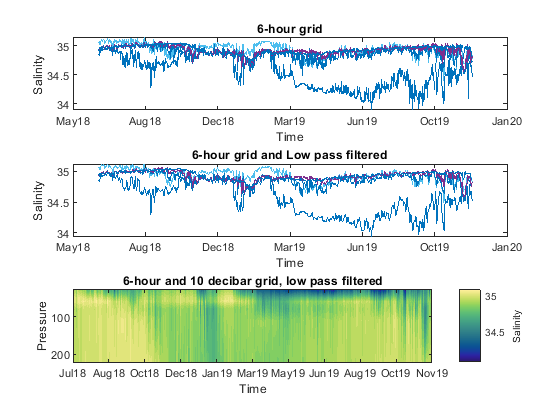

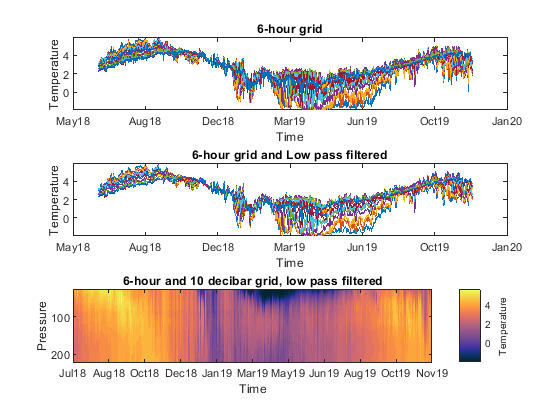

figure(2);
ax(1)=subplot(3,1,1);
plot(data.time_grid,data.temp);
ylabel('Temperature')
xlabel('Time')
datetick('x',12,'keepticks')
title('6-hour grid')

ax(2)=subplot(3,1,2);
plot(data.time_grid,data.temp_filtered);
ylabel('Temperature')
xlabel('Time')
datetick('x',12,'keepticks')
title('6-hour grid and Low pass filtered')

ax(3)=subplot(3,1,3);
[c,h]=contourf(data.time_grid,data.pres_grid,data.temp_filtered_interpolated,30,...
    'Linecolor','none');
axis ij
cmocean('Thermal')
C=colorbar;
ylabel(C,'Temperature')
ylabel('Pressure')
xlabel('Time')
datetick('x',12,'keepticks')
title('6-hour and 10 decibar grid, low pass filtered')
savename=[plot_dir filesep mooring_id '_temp_grid'];
print(gcf, '-dpng',savename);
end
